durat = 1

durat = 1

%visArea = 1
visArea = 1:length(groupRoundXpts{1,n})

visArea =      1     2     3     4     5


%sess = 1
sess = 1:nGroup

sess =      1     2     3



global durat 
global visArea 
global sess 

global uniqueContrasts

[lo_yi_interpedConsCurve_allPtsAllSess,lo_xi_isDf_higherRes_allPtsAllSess,lo_C50_allPtsAllSess,lo_df_at_C50_allPtsAllSess,hi_yi_interpedConsCurve_allPtsAllSess,hi_xi_isDf_higherRes_allPtsAllSess,hi_C50_allPtsAllSess,hi_df_at_C50_allPtsAllSess] = makeC50_test(loRun_allSessAllPtsAllDurs_CRF,hiRun_allSessAllPtsAllDurs_CRF);
% the c50 output vars are pts x column w/df values at c50 x sess (probs better dimsional arrangement for this...)
lo_C50_allPtsAllSess = squeeze(lo_C50_allPtsAllSess);
hi_C50_allPtsAllSess = squeeze(hi_C50_allPtsAllSess);
% w/squeeze they are points x sess
size(lo_C50_allPtsAllSess)

ans =      5     3


size(hi_C50_allPtsAllSess)

ans =      5     3


% bar plot - no error bars
% across the whole group (sessions/mice), what's C50 on average per area?
figure
Y = [mean(lo_C50_allPtsAllSess(1,:),2),mean(hi_C50_allPtsAllSess(1,:),2); mean(lo_C50_allPtsAllSess(2,:),2), mean(hi_C50_allPtsAllSess(2,:),2); mean(lo_C50_allPtsAllSess(3,:),2),mean(hi_C50_allPtsAllSess(3,:),2); mean(lo_C50_allPtsAllSess(4,:),2),mean(hi_C50_allPtsAllSess(4,:),2);]

Y =     0.5417    0.2577
    0.4382    0.1655
    0.4482    0.1714
    0.5079    0.2280


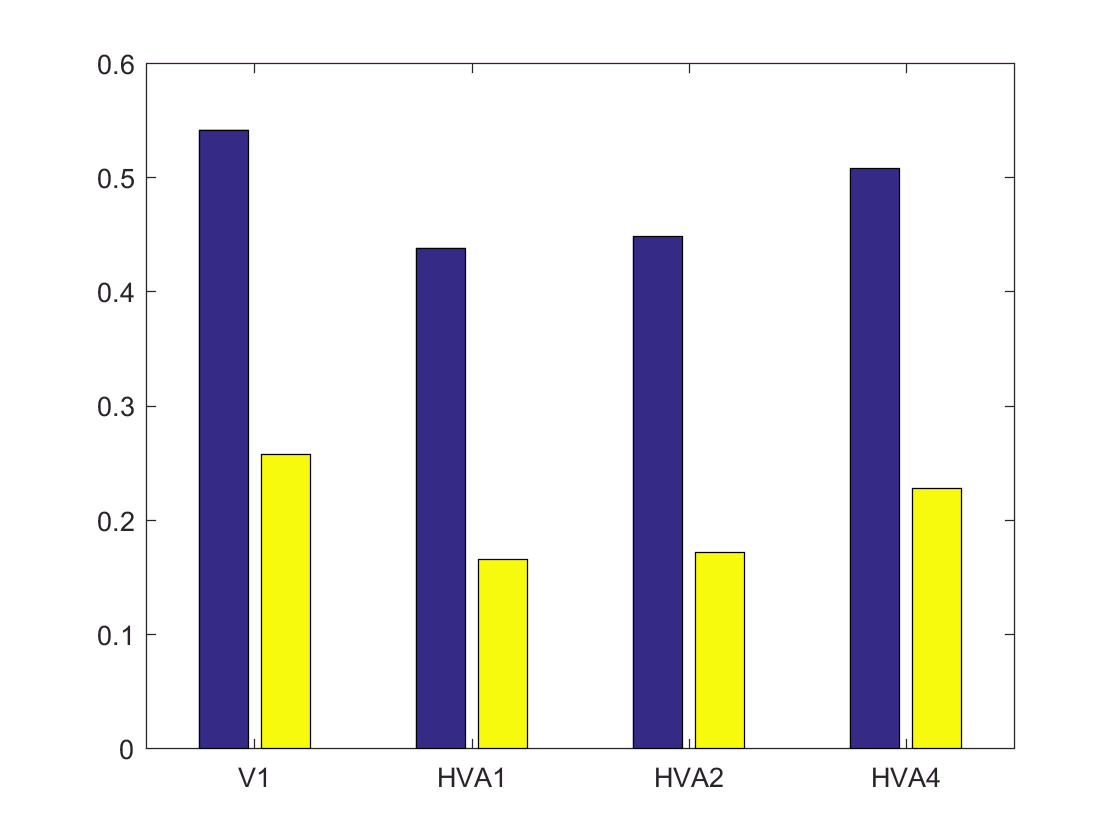

X = [1:4];
areaLabels = {'V1','HVA1','HVA2','HVA4'};
bar(X,Y)
set(gca,'xticklabel',areaLabels)

% get stderr of c50 across sessions, for all points

% need transpose for std to work for some reason
trans_lo_C50_allPtsAllSess = lo_C50_allPtsAllSess';
% gives std for 550 on 1 x # pts matrix
lo_std_C50_acrossSess_AllPts = std(trans_lo_C50_allPtsAllSess);
lo_stdERR_C50_acrossSess_AllPts = lo_std_C50_acrossSess_AllPts/sqrt(nGroup);

% need transpose for std to work for some reason
trans_hi_C50_allPtsAllSess = hi_C50_allPtsAllSess';
% gives std for 550 on 1 x # pts matrix
hi_std_C50_acrossSess_AllPts = std(trans_hi_C50_allPtsAllSess);
hi_stdERR_C50_acrossSess_AllPts = hi_std_C50_acrossSess_AllPts/sqrt(nGroup);

% Q: have I been making error bars too long ?: 
% errorbar(y,err) creates a line plot of the data in y and draws a vertical error bar at each data point. 
% The values in err determine the lengths of each error bar above and below the data points, 
% so the total error bar lengths are double the err values

% bar plot - W/error bars
% across the whole group (sessions/mice), what's C50 on average per area?
figure
Y = [mean(lo_C50_allPtsAllSess(1,:),2),mean(hi_C50_allPtsAllSess(1,:),2); mean(lo_C50_allPtsAllSess(2,:),2), mean(hi_C50_allPtsAllSess(2,:),2); mean(lo_C50_allPtsAllSess(3,:),2),mean(hi_C50_allPtsAllSess(3,:),2); mean(lo_C50_allPtsAllSess(4,:),2),mean(hi_C50_allPtsAllSess(4,:),2);]

Y =     0.5417    0.2577
    0.4382    0.1655
    0.4482    0.1714
    0.5079    0.2280


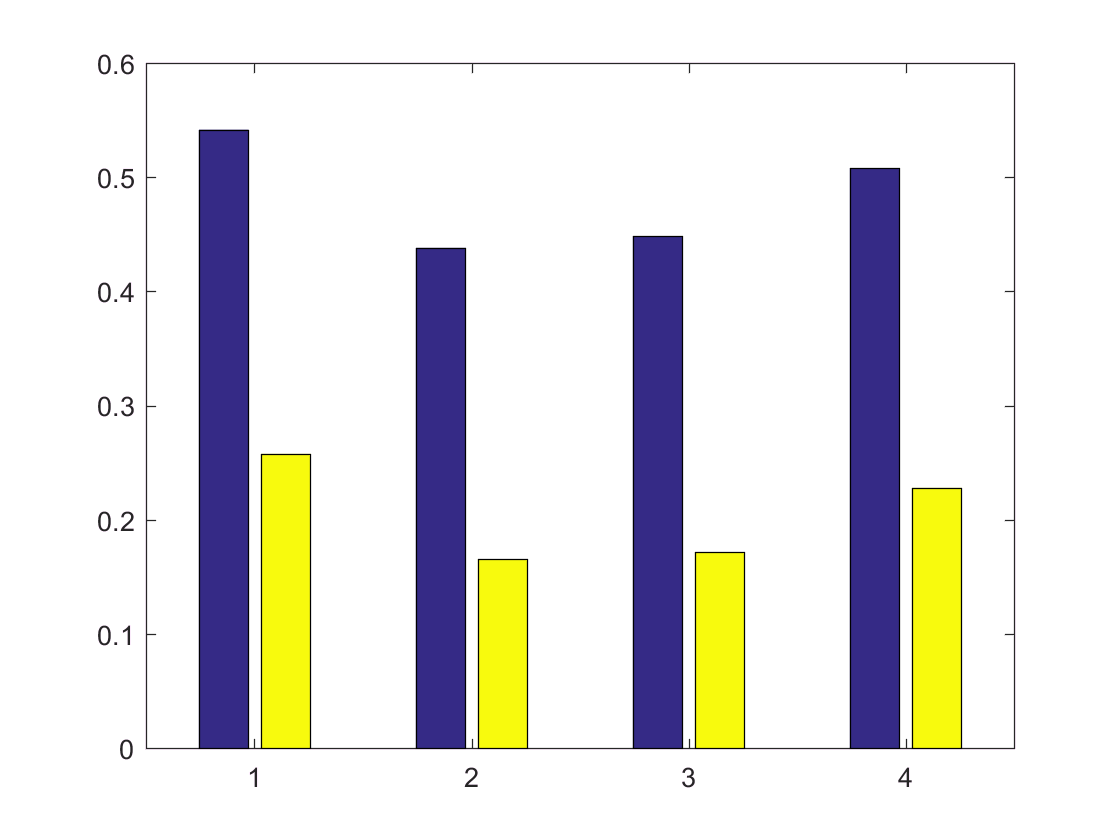

X = [1:4];
areaLabels = {'V1','HVA1','HVA2','HVA4'};
bar(X,Y)

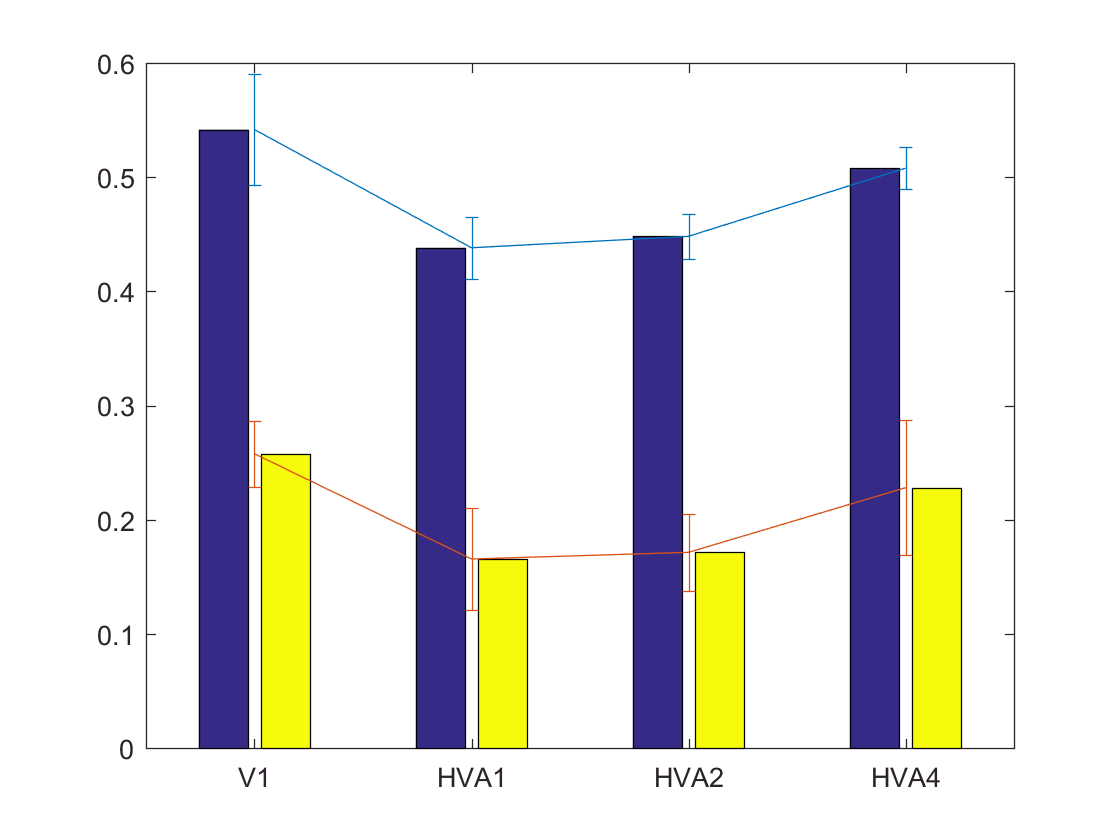

bar(Y)
set(gca,'xticklabel',areaLabels)


hold on

hiAndLo_StdErr = [lo_stdERR_C50_acrossSess_AllPts(1,1:4); hi_stdERR_C50_acrossSess_AllPts(1,1:4)];
trans_Y = Y';
%newX = [1:8];
er = errorbar(trans_Y',hiAndLo_StdErr'); % leave out last stderr cuz its for control point    

%er.Color = [0];                            
%er.LineStyle = 'none';  




x = 1:13;
data = [37.6 24.5 14.6 18.1 19.5 8.1 28.5 7.9 3.3 4.1 7.9 1.9 4.3]';
errhigh = [2.1 4.4 0.4 3.3 2.5 0.4 1.6 0.8 0.6 0.8 2.2 0.9 1.5];
errlow  = [4.4 2.4 2.3 0.5 1.6 1.5 4.5 1.5 0.4 1.2 1.3 0.8 1.9];

bar(x,data)                



hold on

er = errorbar(x,data,errlow,errhigh);    
er.Color = [0 0 0];                            
er.LineStyle = 'none';  

hold off